Lektion 3 - Robot perception

Setup:

rosshutdown

Shutting down global node /matlab_global_node_13652 with NodeURI http://192.168.1.100:54778/


setenv('ROS_MASTER_URI','http://192.168.1.200:11311')
% assuming your own ip is 192.168.1.100
setenv('ROS_IP','192.168.1.100')
rosinit('http://192.168.1.200:11311');

The value of the ROS_IP environment variable, 192.168.1.100, will be used to set the advertised address for the ROS node.
Initializing global node /matlab_global_node_62959 with NodeURI http://192.168.1.100:54794/


Opgave 1 - Image input

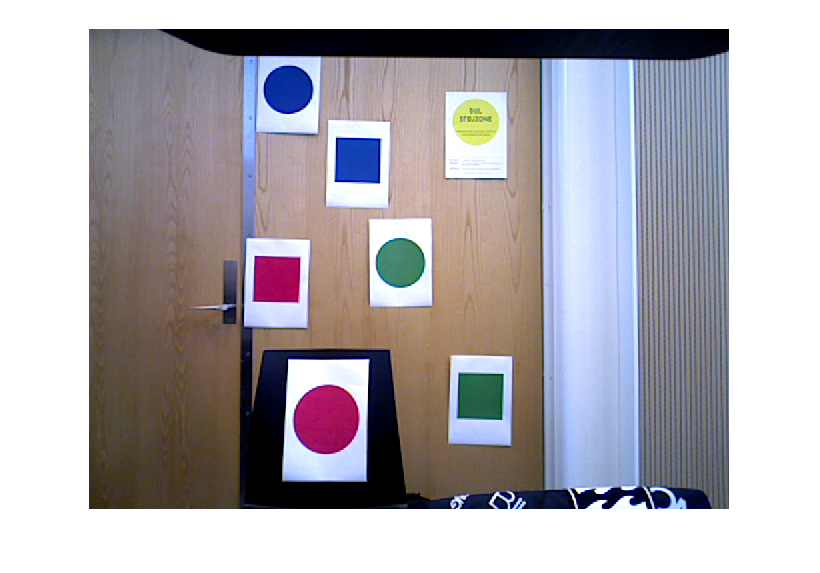

% Grap image from camera
if ismember('/camera/rgb/image_color/compressed',rostopic('list'))
    imsub = rossubscriber('/camera/rgb/image_color/compressed');
end

if ismember('/camera/rgb/image_raw',rostopic('list'))
    imsub = rossubscriber('/camera/rgb/image_raw');
end

imgraw = receive(imsub); % a serialised image
img = readImage(imgraw); % decode image
figure
imshow(img);

Opgave 2 - Calculate k variable:

Z = 2;
X = 0.15

X = 0.1500

x = 43

x = 43

k = 573

k = 573

Opgave 3 - Plot relationen mellem målte objecters længde i pixels og kamera højde. relater dette plot til perspektiv - 

Opgave 4 - Detekter objekter og farver